# **MATH1019 Linear Algebra and Statistics for Engineers**

# **Laboratory Session 10**

**Learning outcomes for this session**

At the end of this session, you will be able to

- Define points, lines and planes in MATLAB.

- Use MATLAB to solve various problems involving points, lines and planes.

Overview

1.      Vector geometry in MATLAB.

2.      MATLAB commands introduced in this worksheet**:  **`ctm_points, ctm_line, ctm_plane, detail, intersection, AreSkewLines, form`

# **Table of Contents:**

# **Background on the **`geom3d`** toolbox:**

 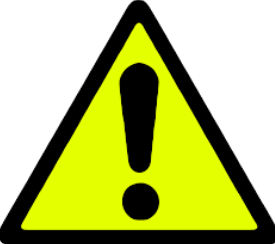  In this lab we'll be using an extra MATLAB library (aka toolbox) called `geom3d`.  This toolbox has already been downloaded for you, but if you're interested (eg: perhaps you want a copy of it), you can download `geom3d` from the **MathWorks **[**FileExchange**](http://au.mathworks.com/matlabcentral/fileexchange/?s_tid=gn_mlc_fx)**.**  Specifically `geom3d` can be found [HERE](http://au.mathworks.com/matlabcentral/fileexchange/24484-geom3d).  

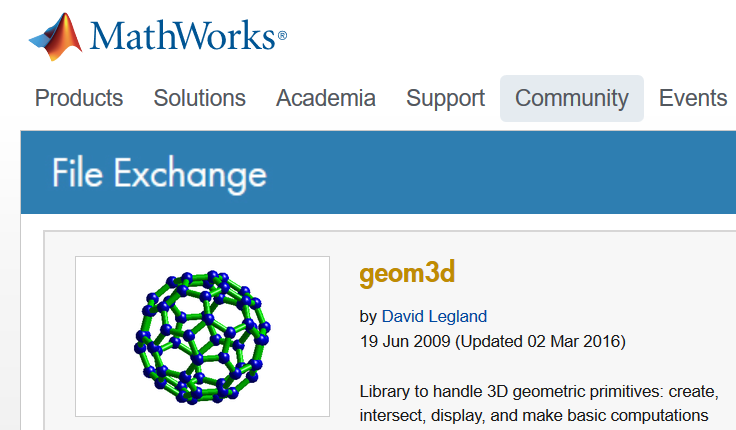

### Load the geom3d toolbox

We'll add some folders to MATLAB's search path:

bh_add_geom3d_to_path

# **Background on **`the ctm_*`** classes**

   In this lab we'll be using 3 custom written MATLAB functions (actually they're classes), called:

- `ctm_points `

- `ctm_line `

- `ctm_plane`

These classes have been developed to provide a simple interface, that supports your learning and exploration of points, lines and planes.

# **Q1:   Points**

A point is usually given a *label* and a *co-ordinate* using the `ctm_point` function. Suppose we want to create a point **A**, with *coordinates* (x,y,z) and a *label* 'hello_A'. This is done using the command:

-  `A = ctm_point('hello_A', x,y,z)`**. **

NOTE:

- *The above syntax creates a variable named ****A**** .  *

- *We also refer to ****A**** as being an object.*

- *You can use any label that you like, but it must be enclosed in single quotes as shown above, eg:  'hello_A'  ... or  ... 'POINT_a', etc*

### 1a.)   Create 2 point variables

Create 2 variables **A** and **B** that define the points A(1, 2, 3) and B(2, -1, 2) by using the `ctm_point` function:

### 1b.)   The `detail` function

The command `detail(``object``)` will give a description of the *object* in question. 

Type in the command `detail(A)`, and note the details given for the variable **A**.  

We can also get this detail by just typing the name of the variable either in the command window or in your script - we call this "echoing" the variable. 

Type **B** to see the details of the **B** variable :

### 1c.)   The `distance` between points

  The distance between two points can be found using the `distance(A,B)` command, for example:

- `the_dist = distance(A,B)`

Find the distance between the two points **A** and **B** defined above.

### 1d.)  Properties of your variables

Sometimes, we may forget what a variable stands for (eg: is it a point, a line, a plane, etc). The command **form(***object*) will tell us what the object is, for example:

- `form(B)`

 Find the form of the variable called **B**.

Alternatively a more general approach is to use the MATLAB command `whos`.  

Type in `whos` to see all of the variables that you have created so far:

# **Q2:   Lines**

### 2a.)   Create a Line - technique 1

A line in 3-space may be defined in different ways. One way is to specify two points. For example to create a line object called **L1, **that passes through the two points **A** and **B** of question 1 we would use the syntax:

-   `L1 = ctm_line( 'Hello_L1', {A, B} ); `

Now you try it and check the `details` by echoing the **L1** variable. 

Echo some details about **L1**:

### 2b.)   Create a Line - technique 2

A line can also be defined by specifying a point and a direction for the line. This syntax has the form:

- `L2 = ctm_line(some_label, {``point``, ``row_vector}``) `

where:

- ***some_label*** - is any descriptive label enclosed in single quotes, eg:  `'hello_L'`

- ***point*** - is a point variable created using the `ctm_point` function

- ***row_vector*** - is a 1x3 numeric matrix defining the direction of the line, eg:  `[11, 22, 33]`

Define the line **L2** which passes through the point **B** and has direction vector [1, 2, 5]. 

Again check your details by echoing the **L2** variable.

### 2c.)   Intersecting Lines  

Two lines will intersect at a point, or, they may be the same line, or the lines may be skewed towards each other.  

Type in the command:

-  `O1 = intersection(L1, L2)` 

where **L1** and **L2** are the two lines defined above. 

The intersection will give rise to the object **O1**, which will be a point in this case. In general, the resulting object may be a point, or a line or NULL when the intersection cannot be computed.   Check your result by echoing the **O1** variable

####  OPTIONAL:   We can visualise these 2 Lines and their point of intersection

Let's plot the lines **L1** and **L2** and the intersection point **O1 **by typing in the following:

TIP*: hover your mouse over the plot and interact with the "exploration" icons that appear(eg: rotate the plot) *

### 2d.)   Create a Line - technique 3

A line may also be defined by specifying its parametric equations. For example if  $x=1+t\;,y=5-2t\;,z=6+7t$  defines a line with parameter *t*, then we can define it with the command:

-  `syms t`

-  `L3 = ctm_line('sarahs_L3', [1+ t, 5 – 2*t, 6+ 7*t], t) `

Because we may have other constants in the definition of the line, we must always tell MATLAB which is the parameter used for the line definition - and this is done using the **syms** command as shown above. 

Now define the two lines  **L4** and **L5** :

- L4:    *x* = 3 + *t*,        *y =* 1 + 2*t*,       *z *= 7 + 5*t*; 

- L5:    *x* = 1 + 2*t*,      *y *= –2*t*,           *z = t*.  

Use the `intersection` command to determine where the lines **L2** and **L4** intersect:

Use the `intersection` command to determine where the lines **L1** and **L5** intersect:

####  OPTIONAL:   We can visualise the L2 and L4 Lines 

Let's plot the lines **L2** and **L4**  by typing in the following:

TIP*: hover your mouse over the plot and interact with the "exploration" icons that appear(eg: rotate the plot) *

####  OPTIONAL:   We can visualise the L1 and L5 Lines

Let's plot the lines **L1** and **L5**  by typing in the following:

TIP*: hover your mouse over the plot and interact with the "exploration" icons that appear(eg: rotate the plot) *

### 2e.)   Are Lines Skewed

Say we've created 2 line variables *line1 *and *line2.  *Then the command:

- `tf_is_skewed =  AreSkewLines(``line1, line2``), `

will return `true` if the lines are skewed and `false` if they are NOT skewed.

Use the `AreSkewLines` function on lines  **L1** and **L5**.

# **Q3:   Planes**

A plane is defined using the syntax:

- `P = ctm_plane( 'kathys_P', {A,B,C} )` 

where:

- **P** is the variable that represents the defined plane  

- **A, B, C** are the variables of three distinct points that lie on the plane.

- **A, B, C **are variables created by using the `ctm_point` function.

Another way to define a plane is to specify a point and a normal vector to the plane. The syntax for this is:

- `Q = ctm_plane('williams_Q', {A, v} ) `

where:

- **Q** is the variable that represents the defined plane

- **A** is a point on the plane (**A** is a variable created using the `ctm_point` function)

- **v** is a numeric row vector that is normal to the plane (eg:  `v`` = [11, 22, 33]` )

### 3a.)   Create a Plane - technique 1   

Define the plane **P1**, which passes through the three points **A1**(1, 2, 4),  **A2**(2, 1, 1) and **A3**(1, 5, 6). Always check your details using by echoing the variables that you have created.  

Use the `ctm_point` function to create your 3 point variables  **A1, A2, A3** :

Echo the points to see their detail, eg:

Use the `ctm_plane` function to create the PLANE and store it in a variable called **P1**:

Use the `details` function with **P1**:

####  OPTIONAL:   We can visualise the plane **P1**

To visualise the **P1** plane, type the following:

TIP*: hover your mouse over the plot and interact with the "exploration" icons that appear(eg: rotate the plot) *

### 3b.)   Create a Plane - technique 2   

Define also the plane **P2**, which passes through the point **B1**( 0, 1, 1) and has normal  directions parallel to the row vector, ***V*** =  [2, 1, 1].

Use the `details` function with **P2**:

### 3c.)   The intersection of 2 planes   

We can use the intersection command to find the intersection of 2 planes.  The syntax is:

- `O4 = intersection(P1,P2)`

Use the `intersection` command on the pair [**P1, P2**], and check your result by echoing the result. What is the result of the intersection?

####  OPTIONAL:   And we can visualise the planes **P1** and **P2** and the line intersection **O4**:

To plot both planes **P1, P2** and the intersection **O4**,  type the following:

TIP*: hover your mouse over the plot and interact with the "exploration" icons that appear(eg: rotate the plot) *

### 3d.)   Create a Plane - technique 3   

A third way to define a plane is by giving its equation directly.  In this case, the command syntax takes the form:

-  `syms x y z`

-  `P3 = ctm_plane('hello_P', a*x+b*y+c*z==d, [x,y,z] ) `

*NOTE: *

- * the use of the double equals sign '==' in the above syntax *

- The third argument is required to tell MATLAB which are the plane variables in the equation.  

Define the plane **P3** with equation `2x + 4y -7z = 9`.

# **Q4:   Distances between things**

Distances between the various pairs of objects: (point, line), (point, plane), (line, line), (line, plane) and (plane, plane) can be found using the `distance` function. In general, if the two objects do not intersect, then the `distance` function will return the shortest distance between them. 

Define the following objects:

- points: A(1, 1, 1),  B(2, 0, 3)

- lines:   L1:  *x* = 1 + *t*, *y* = 2 + *t*, *z* = 3 + 2*t*    and     L2:* x = *2 + *s*,  *y* = 1 – *s* , *z*= 2*s*

- planes: P1: *x*– *y* – *z* =3     and    P2: –2*x* + 2*y* + 2*z* = 5

Find the shortest distances between each pair of objects, using the **distance** function.  The syntax will have the form:

- `some_dist = distance(  THING_1,  THING_2  ) `

### Define the Points using the `ctm_point` function:

### Define the Lines using the `ctm_line` function:

### Define the Planes using the `ctm_plane` function:

#### Now Compute the distances:

The distance from **A** to everything else

The distance from **B** to everything else

The distance from **L1** to everything else

The distance from **L2** to everything else

The distance from** P1** to everything else

The distance from **P2** to everything else

####  OPTIONAL:   Let's visualise some of these things

Visualise the PLANES and the LINES by typing in the following:

Visualise the Planes **P1** and **P2 **by typing:

# **Local Subfunctions only beyond this point**

function bh_add_geom3d_to_path()
    ROOT_DIR = [pwd, filesep, 'geom3d_tbox_fileexchange',filesep,'geom3d'];
    addpath([ROOT_DIR, filesep, 'geom3d'],         '-end')
    addpath([ROOT_DIR, filesep, 'geom3d-demos'],    '-end')
    addpath([ROOT_DIR, filesep, 'meshes3d'],       '-end')
    addpath([ROOT_DIR, filesep, 'meshes3d-demos'], '-end')
   
    % echo the first few elements of our search path
    sp             = path;
    TGT_SPLIT_CHAR = pathsep;
    C              = strsplit(sp, TGT_SPLIT_CHAR);
    
    fprintf('\n');
    fprintf('\n Have just added the GEOM3D toolbox to the MATLAB path');
    fprintf('\n%s',repmat('-',1,50));
    fprintf('\n    ---> %s', C{(end-3):end});
    fprintf('\n%s',repmat('-',1,50));
    fprintf('\n');
end